#### Name : Ghosh Kushanava Amitava

#### Roll No : 220123083

#### Course : MA 423

format long e

**Q.1**

(a)  Generate **Wilkinson Matrix** **without using for loops**

n = input("Enter the size of Wilkinson Matrix: ")

n =        4       


W = Wilkinson(n)

W =        1              0              0              1       
      -1              1              0              1       
      -1             -1              1              1       
      -1             -1             -1              1       


(b)  Generate **random real** **Hamiltonian Matrix of order 2n x 2n**

n = input("Enter the size of Hamiltonian Matrix: ")

n =        4       


H = Hamiltonian(n)

H =     -903/416       1935/3811      1060/2787         2/46305     1103/2576       575/642       1046/1431       809/1400  
    -669/11303     1073/634      -1107/1097      -493/1551       575/642       1191/1759       450/791       -317/1240  
   -2376/2351       936/1583       -63/3229      1556/1421      1046/1431       450/791      -2195/1488     -1035/4423  
    1436/2337      -623/968       -145/3007     -1160/619        809/1400      -317/1240     -1035/4423      -126/359   
     397/637        672/841       1353/1438     -1129/1138       903/416        669/11303     2376/2351     -1436/2337  
     672/841        319/1341      -649/644       -653/880      -1935/3811     -1073/634       -936/1583       623/968   
    1353/1438      -649/644       2512/6443       219/2489     -1060/2787      1107/1097        63/3229       145/3007  
   -1129/1138      -653/880        219/2489      -493/519         -2/46305      493/1551     -1556/1421      1160/619   


**Q.2** 

Generate a random matrix A and compute the following:

A = rand(8)

A =      6.847912614990556e-01     4.889125902077860e-01     9.603096728937129e-01     2.770651688203120e-01     5.685407631360883e-01     5.513898659237024e-01     2.662223259639943e-01     2.407662474947856e-01
     9.217251965747647e-01     4.909153360927446e-01     4.108521267303225e-01     1.711066129065541e-01     7.632202882152594e-01     4.251817563839118e-01     7.338821689621505e-02     3.679280384452761e-01
     2.682210772849049e-01     4.587028181935869e-01     8.415938049653792e-01     1.505015207872805e-01     1.410429069112747e-01     1.633065579501121e-01     3.797293307291301e-01     8.487803567983400e-01
     2.279755516910923e-01     3.245503644073657e-01     9.755631353642236e-01     6.240033172370663e-01     1.980531897425594e-01     8.093239289431612e-01     6.465363002687142e-01     9.991169945992462e-01
     4.011294515517621e-01     5.841388701113779e-01     6.182549557733991e-01     7.657193592669009e-01     5.880239963974759e-01     4.440078986902571e-01    

(a)  Find Maximum Value in each column

maxColumn = max(A)

maxColumn =      9.217251965747647e-01     8.712305920140229e-01     9.755631353642236e-01     7.657193592669009e-01     8.406931441857629e-01     8.093239289431612e-01     6.465363002687142e-01     9.991169945992462e-01


(b)  Find Maximum Value in each row

maxRow = max(A, [], 2)

maxRow =      9.603096728937129e-01
     9.217251965747647e-01
     8.487803567983400e-01
     9.991169945992462e-01
     7.657193592669009e-01
     8.406931441857629e-01
     8.712305920140229e-01
     8.613012673536818e-01


(c)  Find Overall Maximum Value

maxValue = max(A(:))

maxValue =      9.991169945992462e-01


(d)  Find the row and column indices of all elements **larger than 0.25**

[rowIndex, colIndex] = find(A > 0.25)

rowIndex =      1
     2
     3
     5
     6
     7
     8
     1
     2
     3


colIndex =      1
     1
     1
     1
     1
     1
     1
     2
     2
     2


**Q.3**

Generate **Magic Squares of order n x n** and verify the **summation property**

n = input("Enter the size of Magic Square Matrix: ")

n =      4


M = magic(n)

M =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


(a)  Row Sums

rowSums = sum(M, 2)

rowSums =     34
    34
    34
    34


(b)  Column Sums

columnSums = sum(M, 1)

columnSums =     34    34    34    34


(c)  Main Diagonal Sum

mainDiagSum = trace(M)

mainDiagSum =     34


(d)  Anti Diagonal Sum

antiDiagSum = trace(flip(M))

antiDiagSum =     34


Check for **Summation Property**

check = all(rowSums == rowSums(1)) && all(columnSums == columnSums(1)) && mainDiagSum == rowSums(1) && antiDiagSum == rowSums(1);
if check
    disp("All sums are equal - Valid Magic Square")
else
    disp("All sums are NOT equal")
end

All sums are equal - Valid Magic Square


**Q.4**

Consider a magic square A for n = 3, 4, 5

n = input("Enter the size of Magic Square Matrix: ")

n =      4


A = magic(n)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


(a)  What do the following do?

sum(A)

ans =     34    34    34    34


sum(A) command computes the sum of individual column elements of A and returns a row vector of it

sum(A')'

ans =     34
    34
    34
    34


sum(A')' command computes the sum of individual row elements of A and returns a column vector of it

sum(diag(A))

ans =     34


sum(diag(A)) computes the sum of elements present in the main diagonal of A

sum(diag(flipud(A)))

ans =     34


sum(diag(flipud(A)) computes the sum of elements present in the anti diagonal of A

rank(A)

ans =      3


rank(A) computes the rank of A

(b)  Do the following commands

p = randperm(n);
q = randperm(n);
A = A(p, q);

sum(A)

ans =     34    34    34    34


sum(A')'

ans =     34
    34
    34
    34


sum(diag(flipud(A)))

ans =     40


rank(A)

ans =      3


When compared with the outputs in (a). The value of sum(diag(flipud(A))) changes.

(c)  The magic square A = magic(4) is singular. What do

null(A)

ans =      2.236067977499788e-01
    -6.708203932499371e-01
    -2.236067977499788e-01
     6.708203932499368e-01


null(A) in this case returns** 1 column** which implies that the **null-space** is **1-D** and columns of A are linearly dependent

null(A, 'r')

ans =      3.333333333333333e-01
    -1.000000000000000e+00
    -3.333333333333333e-01
     1.000000000000000e+00


null(A, 'r') represents the linear combination of columns A that sums to **zero** in this case which implies that columns of A are linearly dependent

rref(A)

ans =      1.000000000000000e+00                         0                         0    -3.333333333333333e-01
                         0     1.000000000000000e+00                         0     1.000000000000000e+00
                         0                         0     1.000000000000000e+00     3.333333333333333e-01
                         0                         0                         0                         0


rref(A) gives the reduced row echelon form of A and in this case it has **3 non-zero rows (rank = 3)** which implies that **1 column** is a linear combination of others. Hence, columns of A are linearly dependent

**Q.5**

Are the following true or false? Assume A is a generic n x n matrix

n = input("Enter the size of Generic Matrix: ")

n =      4


A = randi(10, n, n)

A =      4     8     9    10
     6     1     6     2
     8     7     8     9
     6     5     2     2


(a)  A^(-1) equals 1./A ?

A^(-1)

ans =     -1.896551724137931e-01     4.310344827586226e-03     2.068965517241378e-01     1.293103448275868e-02
     2.183908045977011e-01    -2.011494252873566e-02    -2.988505747126436e-01     2.729885057471264e-01
     2.183908045977011e-01     2.298850574712644e-01    -2.988505747126436e-01     2.298850574712645e-02
    -1.954022988505747e-01    -1.925287356321839e-01     4.252873563218391e-01    -2.442528735632184e-01


1./A

ans =      2.500000000000000e-01     1.250000000000000e-01     1.111111111111111e-01     1.000000000000000e-01
     1.666666666666667e-01     1.000000000000000e+00     1.666666666666667e-01     5.000000000000000e-01
     1.250000000000000e-01     1.428571428571428e-01     1.250000000000000e-01     1.111111111111111e-01
     1.666666666666667e-01     2.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01


The above statement is **False**

(b)  A.^ (-1) equals 1./A ?

A.^(-1)

ans =      2.500000000000000e-01     1.250000000000000e-01     1.111111111111111e-01     1.000000000000000e-01
     1.666666666666667e-01     1.000000000000000e+00     1.666666666666667e-01     5.000000000000000e-01
     1.250000000000000e-01     1.428571428571428e-01     1.250000000000000e-01     1.111111111111111e-01
     1.666666666666667e-01     2.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01


1./A

ans =      2.500000000000000e-01     1.250000000000000e-01     1.111111111111111e-01     1.000000000000000e-01
     1.666666666666667e-01     1.000000000000000e+00     1.666666666666667e-01     5.000000000000000e-01
     1.250000000000000e-01     1.428571428571428e-01     1.250000000000000e-01     1.111111111111111e-01
     1.666666666666667e-01     2.000000000000000e-01     5.000000000000000e-01     5.000000000000000e-01


The above statement is **True**

**Q.6**

Suppose p is a row vector consisting of coefficents of a polynomial. What does the following line do? 

p = [1 2 3 4]; % p(x) = x^3 + 2x^2 + 3x + 4
(length(p)-1:-1:0) .* p

ans =      3     4     3     0


This command does an **element-wise multiplication** between a **vector of exponents** (from highest to 0) and **vector p of polynomial coefficients. **Basically, it computes the **coefficients** **of** **derivative** of the polynomial

**Q.7**

(a)  Use diag to build the 16 x 16 matrix

n = 16;

D = diag(-2 * ones(n, 1));
D = D + diag(ones(n - 1, 1), 1);
D = D + diag(ones(n - 1, 1), -1);
D = D + diag(ones(1, 1), n - 1);
D = D + diag(ones(1, 1), 1 - n);
D

D =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


(b)  Now read about **toeplitz** and use it to build D.

c = zeros(n, 1);
c(1) = -2;
c(2) = 1;
c(n) = 1;
D = toeplitz(c);
D

D =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


(c)   Use **toeplitz** to build following matrix

c = [1:8];
X = triu(toeplitz(c))

X =      1     2     3     4     5     6     7     8
     0     1     2     3     4     5     6     7
     0     0     1     2     3     4     5     6
     0     0     0     1     2     3     4     5
     0     0     0     0     1     2     3     4
     0     0     0     0     0     1     2     3
     0     0     0     0     0     0     1     2
     0     0     0     0     0     0     0     1


Y = toeplitz(1./c)

Y =      1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01     1.428571428571428e-01     1.250000000000000e-01
     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01     1.428571428571428e-01
     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01
     2.500000000000000e-01     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01
     2.000000000000000e-01     2.500000000000000e-01     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01    

format rat
Y

Y =        1              1/2            1/3            1/4            1/5            1/6            1/7            1/8     
       1/2            1              1/2            1/3            1/4            1/5            1/6            1/7     
       1/3            1/2            1              1/2            1/3            1/4            1/5            1/6     
       1/4            1/3            1/2            1              1/2            1/3            1/4            1/5     
       1/5            1/4            1/3            1/2            1              1/2            1/3            1/4     
       1/6            1/5            1/4            1/3            1/2            1              1/2            1/3     
       1/7            1/6            1/5            1/4            1/3            1/2            1              1/2     
       1/8            1/7            1/6            1/5            1/4            1/3            1/2            1       


**Q.8**

Fibonacci Sequence Script

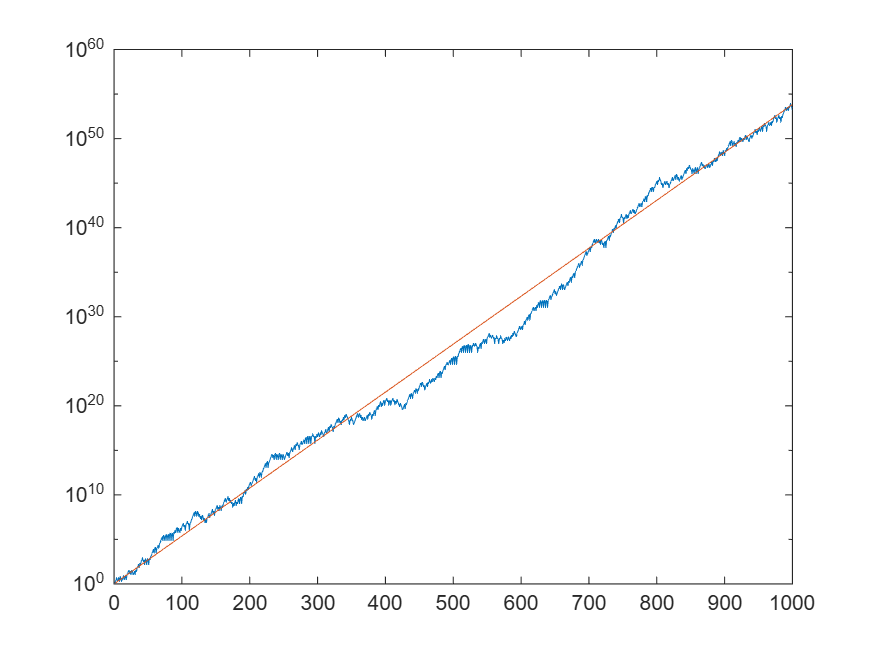

clear
rand('state', 1000)
x = [1, 2];
for n=2:999, x(n+1) = x(n)+sign( rand-0.5)*x(n-1); end
semilogy (1:1000, abs(x))
c = 1.13198824;
hold on
semilogy(1:1000, c.^ [1:1000])
hold off

This script simulates a ***random Fibonacci sequence*** and compares its growth to an exponential function **c^n**, where **c ≈ 1.13198824**. The goal is to observe if the magnitude of the sequence |x_n| behaves like **O(c^n)**.

**Q.9**

Solution of system of equations **Ax = b**

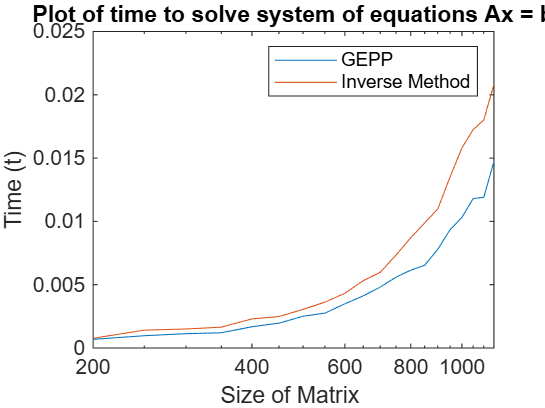

m = (200: 50: 1150);
t1 = zeros(1, length(m));
t2 = zeros(1, length(m));
for i = 1: length(m)
    A = rand(m(i));
    b = rand(m(i), 1);

    tic;
    x = A\b;
    t1(i) = toc;

    tic;
    x = inv(A) * b;
    t2(i) = toc;
end

semilogx(m, t1, m, t2);
title("Plot of time to solve system of equations Ax = b")
legend("GEPP", "Inverse Method")
xlabel("Size of Matrix ")
ylabel("Time (t)")

**Functions**

function W = Wilkinson(n)
    % This function creates a Wilkinson Matrix of order n x n
    % W[i][j] = -1 if i > j, 1 if i = j or j = n, 0 otherwise

    W = 2 * eye(n) - tril(ones(n));
    W(:, end) = 1;
end

function H = Hamiltonian(n)
    % This function creates a random real Hamiltonian Matrix of order 2n x 2n
    % H = [[H_11, H_12], [H_21, -H_11T]]; H_12T = H_12 & H_21 = H_21T

    H_11 = randn(n);
    H_12 = randn(n);
    H_12 = tril(H_12) + tril(H_12).' - diag(H_12) .* eye(n);
    H_21 = randn(n);
    H_21 = tril(H_21) + tril(H_21).' - diag(H_21) .* eye(n);
    H = [H_11, H_12; H_21, -H_11.'];
end